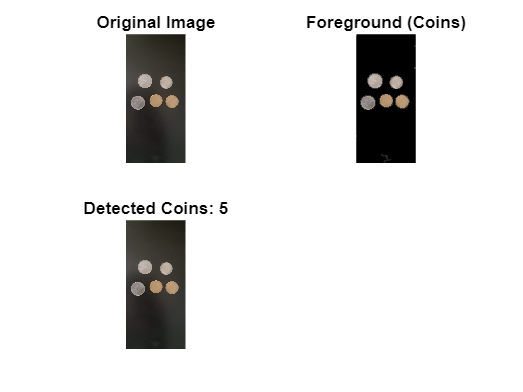

% Read the image
image = imread('newimc.jpg');  % Replace 'INDIAN-COINS.jpg' with your image path

% Convert to grayscale
grayImage = rgb2gray(image);

% Apply Gaussian blur to reduce noise
blurredImage = imgaussfilt(grayImage, 2);

% Use edge detection (Canny method)
edges = edge(blurredImage, 'Canny');

% Dilate the edges to close gaps
dilatedEdges = imdilate(edges, strel('disk', 10));

% Fill the holes in the dilated edges
filledEdges = imfill(dilatedEdges, 'holes');

% Remove small objects
cleanedImage = bwareaopen(filledEdges, 50);

% Invert the cleaned image to create a mask of the background
backgroundMask = ~cleanedImage;

% Remove background from the original image
foregroundImage = bsxfun(@times, image, cast(~backgroundMask, 'like', image));

% Circle detection using Hough transform
radiiRange = [22 1000]; % Range of expected radii of coins (adjust as needed)
[centers, radii, metric] = imfindcircles(edges, radiiRange);

% Count the number of detected circles (coins)
numCoins = length(radii);

% Display the results
figure;
subplot(2, 2, 1), imshow(image), title('Original Image');
subplot(2, 2, 2), imshow(foregroundImage), title('Foreground (Coins)');
subplot(2, 2, 3), imshow(image), title(['Detected Coins: ', num2str(numCoins)]);


% Display the number of coins
disp(['Number of detected coins: ', num2str(numCoins)]);

Number of detected coins: 5
